# Discrete Fourier Transform

**Author:** M. Schoukens - Eindhoven University of Technology

**License and Disclaimer: **BSD 3-Clause "New" or "Revised" License - [link](https://github.com/MaartenSchoukens/SysId-LiveScripts/blob/main/LICENSE)

**Cite As:** M. Schoukens, *SysId LiveScripts - Discrete Fourier Transform*, Eindhoven University of Technology, [https://github.com/MaartenSchoukens/SysId-LiveScripts,](https://github.com/MaartenSchoukens/SysId-LiveScripts,) 2026.

This code is developed and tested in Matlab R2025b Update 3

clear all % clear workspace
close all % close all figures
clc % clear command window

This livescript explores the use of the Discrete Fourier Transform (DFT), the concepts of aliasing, leakage, and energy in the frequency domain with the use of a sine signal example. A brief, but incomplete, overview of the Fourier transform theory is provided below. The reader is referred to one of the many (signal processing) textbooks that are available on this topic for more information.

## From Time to Frequency Domain

### Fourier Transform Basics

The Fourier transform and the inverse Fourier transform


$$U(f)=\int_{-\infty}^{\infty}u(t)e^{-i2\pi ft}dt$$
 


$$u(t)=\int_{-\infty}^{\infty}U(f)e^{i2\pi ft}df$$
 

have been introduced to transform continuous time signals or functions to the frequency domain and back, where $i$ is the imaginary unit, $t$ the continuous time in seconds and $f$ is the frequency in Hz. 

The Fourier transform has a number of interesting properties, including:

- Linearity: the Fourier transform is a linear transformation, i.e. $\mathcal{F}(a u_1(t) + b u_2(t)) = a \mathcal{F}(u_1(t)) + b \mathcal{F}(u_2(t)) $, where $\mathcal{F}(.)$ denotes the fourier transform operation.

- Complex conjugate symmetry: for real-valued time-domain signals we have that $U(f) = \bar{U}(-f)$, where $\bar{.}$ denotes the complex conjugate operation.

### From Fourier Transform to Discrete Fourier Transform

When handling measured signals two important observations can be made:

- Measured signals are sampled, most often at equidistant sampling intervals, with a sampling frequency $f_s$ or sampling interval $T_s = 1/f_s$.

- The transform considers and infinite time interval, while measurements are of finite length in practice.

Including these considerations in the Fourier transform leads to the Discrete Fourier Transform (DFT):


$$U_{DFT}(n)=\sum_{k=0}^{N-1}u(kT_s)e^{-j2\pi nk/N}$$


*Step 1: Discretization in time. *When working with sampled signals, the integral over the continuous time signal $u(t)$ is replaced by the summation over the discrete time (sampled) signal $u(kT_s), \; k\in \mathbb{Z}$:


$$U(f)=\int_{-\infty}^{\infty}u(t)e^{-i2\pi ft}dt \quad \rightarrow \quad U(f) = \sum_{k = -\infty}^{\infty}u(kT_s)e^{-i2\pi f k T_s}$$
 

The resulting transformation is also called the Discrete-Time Fourier Transform (DTFT). An important consequence of the discretization in time is that the spectrum becomes periodic with a periodicity of $f_s$:


$$U(f) = \sum_{k = -\infty}^{\infty}u(kT_s)e^{-i2\pi f k T_s} 
 = \sum_{k = -\infty}^{\infty}u(kT_s)e^{-i2\pi f k T_s}e^{i2\pi k f_s T_s}
 = \sum_{k = -\infty}^{\infty}u(kT_s)e^{-i2\pi (f + f_s) k T_s}
= U(f+f_s)
$$


where we made use of $f_sT_s = 1$, and $e^{i2\pi k}=1 \; \forall k\in\mathbb{Z}$.

*Step 2: Finite length.* When only a finite number of samples are measured, the sum over the infinite interval is replaced by a finite interval $[0,NT_s)$:


$$U(f) = \sum_{k = -\infty}^{\infty}u(kT_s)e^{-i2\pi f k T_s} \quad \rightarrow \quad U(f) = \sum_{k = 0}^{N-1}u(kT_s)e^{-i2\pi f k T_s}$$


While this summation can be evaluated for all possible $f$, the exponential $e^{-i2\pi f k T_s}$ evaluated on the discrete frequency grid $f_n=nf_0=n f_s/N$, $n\in\{0,1,\dots,N-1\}$provides an orthogonal basis over the considered time window $T_0 = 1/f_0 = N/f_s$. The orthogonality property can easily be verified:


$$\frac{1}{N} \sum_{k=0}^{N-1} e^{-i2\pi n_1 f_0 k T_s}e^{i2\pi n_2 f_0 k T_s} = \frac{1}{N} \sum_{k=0}^{N-1} e^{-i2\pi (n_1-n_2) f_0 k T_s} = \delta(n_1-n_2)$$


where  $\delta(n_1-n_2) = 1$ for $n_1=n_2$ and 0 everywhere else.

Hence, the finite-length sampled time-domain signal $u(k)$ can be reconstructed exactly by only considering the discrete frequencies $f_n$, and the continuous frequency $f$ is replaced by the discrete frequency index $n$ resulting in the Discrete Fourier Transform (DFT):


$$U(f) = \sum_{k = 0}^{N-1}u(kT_s)e^{-i2\pi f k T_s} \quad \rightarrow \quad U_{DFT}(n) = \sum_{k = 0}^{N-1}u(kT_s)e^{-i2\pi f_n k T_s} = \sum_{k = 0}^{N-1}u(kT_s)e^{-i2\pi n k /N}$$


The inverse DFT (IDFT) is given by:


$$u(kTs) = \frac{1}{N} \sum_{n= 0}^{N-1}U(n)e^{i2\pi n k /N}$$


The next sections of this livescript study the effect of the discretization in time and frequency domain using the spectrum of a sine wave. We also simplify the notation; the sampling time will be dropped from the discrete-time signal notation $u(kT_s) \rightarrow u(k)$ and the DFT spectrum will drop the DFT subscript $U_{DFT}(n) \rightarrow U(n)$.

## Example: The Spectrum of a Sine Wave

### Sine Spectrum

By decomposing a sine in its complex exponential form, it becomes clear that it is composed by a negative and positive frequency and that this positive and negative frequency are each others complex conjugate:


$$\sin(2\pi f t) = \frac{e^{i2\pi f t} - e^{-i2\pi f t}}{2i}$$


The script below visualizes the time domain evolution and amplitude spectrum of a sine wave for a user-defined frequency and amplitude.

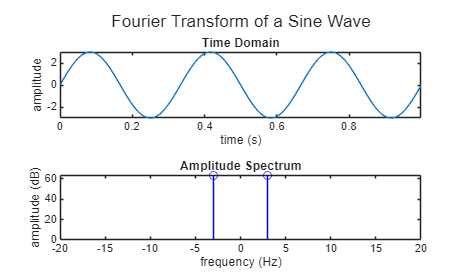

fSine = 3; % frequency of the sine signal
ASine = 3; % time-domain amplitude of the sine signal
Ts = 0.001;
N = 1000;
ASineFreq = ASine*N/2;
t = 0:Ts:(N-1)*Ts;
uSine = ASine*sin(2*pi*fSine*t);

figure; tcl = tiledlayout(2,1); title(tcl,'Fourier Transform of a Sine Wave')
% plot time-domain signal
nexttile; plot(t,uSine); 
title('Time Domain'); xlabel('time (s)'); ylabel('amplitude'); xlim([t(1), t(end)])
% plot amplitude spectrum 
nexttile; stem([-fSine, fSine],db(ASineFreq)*ones(1,2),'b'); % plot negative and positive frequency
title('Amplitude Spectrum'); xlim([-20,20]); xlabel('frequency (Hz)');  ylabel('amplitude (dB)')

The amplitude spectrum is plotted in dB ($\mathrm{dB}(x) = 20 \mathrm{log}_{10}(|x| )$). Note, 0 dB = 1 and every step of -20 dB is a factor 10 smaller. Hence, an amplitude 60 dB lower than another amplitude is in reality$10^{3}$ times smaller.

### Sampling in Time - Spectrum Periodicity

As mentioned earlier, by sampling a continuous time signal in time, the frequency spectrum becomes periodic with periodicity $f_s$. This can also be visualized in the time domain as infinitely many frequencies can go exactly through an equidistantly sampled sine wave.

The code below illustrates this using a user-specified sampling frequency and sine wave frequency. The top sub-figure shows the obtained data after sampling, and the lowest and second lowest sine wave that exactly contains the sampled data. The bottom sub-figure shows how these two frequencies are related through the sampling frequency $f_s$ and Nyquist frequency $f_s/2$, and it also depicts all the other frequencies that exactly reconstruct the sampled data. This illustrates the periodicity of the spectrum of a sampled signal.

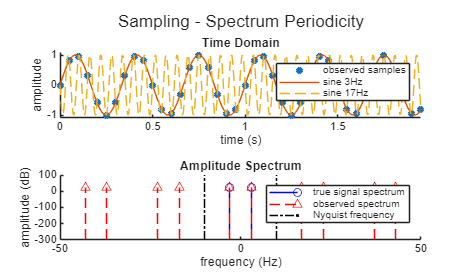

fs = 20; % sampling frequency (Hz)
fSine = 3; % frequency of the sine signal (Hz)
ASine = 1; % time-domain amplitude of the sine signal
N = 40;
ASineFreq = ASine*N/2;
fSineDT = [-fSine,fSine];
fsGrid = -10*fs:fs:10*fs;
% fSinePlot = kron(fsGrid,fSineDT);

fSinePlot = fsGrid - fSineDT'; fSinePlot = sort(fSinePlot(:))';

t = 0:1/fs:(N-1)/fs;
tUp = 0:1/(100*fs):(N-1)/fs;
uSineSamples = ASine*sin(2*pi*fSine*t);
uSine = ASine*sin(2*pi*fSine*tUp);
uSineUp = ASine*sin(2*pi*(fs-fSine)*tUp+pi);


figure; tcl = tiledlayout(2,1); title(tcl,'Sampling - Spectrum Periodicity')
% time domain plot
nexttile; hold on;
plot(t,uSineSamples,'x','MarkerSize',5,'LineWidth',3);
plot(tUp,uSine,'-');
plot(tUp,uSineUp,'--');
xlim([0,t(end)]); ylim([-1.1*ASine 1.1*ASine]); xlabel('time (s)'); ylabel('amplitude')
title('Time Domain'); legend('observed samples',['sine ' num2str(fSine) 'Hz'],['sine ' num2str(fs-fSine) 'Hz'])
% plot spectrum
nexttile; hold on;
stem([-fSine fSine],db(ASineFreq)*ones(1,2),'b','BaseValue',-300); % plot negative and positive frequency
stem(fSinePlot,db(ASineFreq)*ones(1,length(fSinePlot)),'--r^','BaseValue',-300);yl = ylim;
stem([-fs/2,fs/2],300*ones(1,2),'-.k.','BaseValue',-300); % plot Nyquist frequency
ylim(yl); xlim([-50,50]); xlabel('frequency (Hz)');  ylabel('amplitude (dB)')
title('Amplitude Spectrum'); legend('true signal spectrum','observed spectrum','Nyquist frequency')

### Sampling in Time - Aliasing

An important consequence of the spectrum periodicity observed in the previous section is that we cannot exactly know which underlying continuous-time signal $u(t)$generated the sampled data $u(k)$. This results in the often used Nyquist-Shannon sampling theorem, stating that the sampling frequency $f_s$ needs to be greater than twice the highest frequency component in the continuous time signal $u(t)$. The frequency content beyond the Nyquist frequency $f_s/2$ will be mirrored back into the $-f_s/2$ to $f_s/2$ interval, making it impossible to distinguish from lower frequency spectral signal content using conventional techniques. This phenomenon where high-frequency content appears as lower frequencies is called aliasing.

The script below allows the user to observe this aliasing effect for varying sampling and sine wave frequencies.

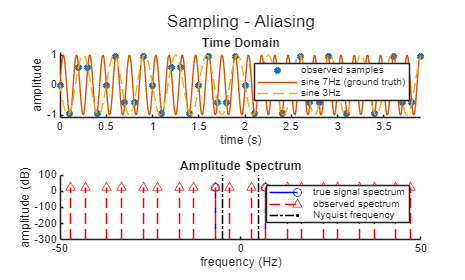

fs = 10; % sampling frequency (Hz)
fSine = 7; % frequency of the sine signal (Hz)
N = 40;
ASine = 1; % time-domain amplitude of the sine signal
ASineFreq = ASine*N/2;
fSineDT = [-fSine,fSine];
fsGrid = -10*fs:fs:10*fs;

fSinePlot = fsGrid - fSineDT'; fSinePlot = sort(fSinePlot(:))';

t = 0:1/fs:(N-1)/fs;
tUp = 0:1/(100*fs):(N-1)/fs;
uSineSamples = ASine*sin(2*pi*fSine*t);
uSine = ASine*sin(2*pi*fSine*tUp);
uSineUp = ASine*sin(2*pi*(fs-fSine)*tUp+pi);

figure; tcl = tiledlayout(2,1); title(tcl,'Sampling - Aliasing')
% time domain plot
nexttile; hold on;
plot(t,uSineSamples,'x','MarkerSize',5,'LineWidth',3);
plot(tUp,uSine,'-');
plot(tUp,uSineUp,'--');
xlim([0,t(end)]); ylim([-1.1*ASine 1.1*ASine]); xlabel('time (s)'); ylabel('amplitude')
title('Time Domain'); legend('observed samples',['sine ' num2str(fSine) 'Hz (ground truth)'],['sine ' num2str(fs-fSine) 'Hz'])
% plot spectrum
nexttile; hold on;
stem([-fSine fSine],db(ASineFreq)*ones(1,2),'b','BaseValue',-300); % plot negative and positive frequency
stem(fSinePlot,db(ASineFreq)*ones(1,length(fSinePlot)),'--r^','BaseValue',-300);yl = ylim;
stem([-fs/2,fs/2],300*ones(1,2),'-.k.','BaseValue',-300); % plot Nyquist frequency
ylim(yl); xlim([-50,50]); xlabel('frequency (Hz)');  ylabel('amplitude (dB)')
title('Amplitude Spectrum'); legend('true signal spectrum','observed spectrum','Nyquist frequency')

### Finite Signal Length - Leakage

As explained in the theory introduction, when a signal has a final length, instead of having a continuous spectrum, a discrete spectral grid is obtained. Energy at frequencies that do not align with this spectral frequency grid will be spread over all frequencies of this grid. This is called spectral leakage: spectral content from one frequency leaks to neighboring frequencies. However, if signals have an integer number of periods within the considered total measurement window, i.e. $f = n/T_0 = n f_0 = n f_s/N$, no leakage will be present.

One can visualize the leakage effect by plotting the considered sine wave over a larger time window, if the continuation of the sine signal beyond the time window exactly overlaps with the repetition of the sine wave as observed in the time window, no leakage will be present. However, if this is not the case, i.e. the signal was not periodic with a periodicity of $T_0 = 1/f_0 = NT_s = N/f_s$, then leakage will occur.

Using the code below, the user can modify the considered frequency grid by choosing different $f_s$ and $N$ values. Furthermore, the sine wave frequency can be chosen to be on or off the frequency grid. For instance choosing $f_s = 10$, $f = 0.8$, and $N=50$ results in an amplitude spectrum that we expect for a sine wave. However, choosing $f_s = 10$, $f = 0.9$, and $N=50$ illustrates the presence of leakage. Note that values at -300 dB are at the Matlab numerical accuracy level (-300 dB = $10^{-15}$), they are equivalent to 0 for practical purposes.

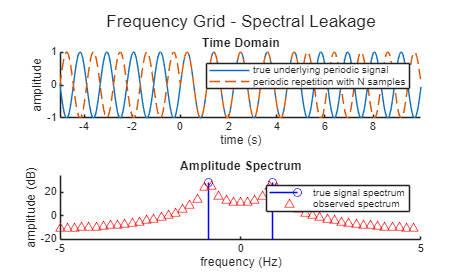

fs = 10; % sampling frequency (Hz)
fSine = 0.9; % frequency of the sine signal (Hz)
N = 50; % length of the signal in number of samples
ASine = 1; % time-domain amplitude of the sine signal
ASineFreq = ASine*N/2;
f0 = fs/N;
nUp = 10; % oversampling factor for time domain plots

t = 0:1/fs:(N-1)/fs;
uSine = ASine*sin(2*pi*fSine*t); 
tExtendedUp = -N/fs:1/(nUp*fs):(2*N/fs-1/(nUp*fs));
uSineUp = ASine*sin(2*pi*fSine*tExtendedUp); 
uSinePeriodicUp = [uSineUp(N*nUp+1:2*N*nUp), uSineUp(N*nUp+1:2*N*nUp), uSineUp(N*nUp+1:2*N*nUp)];

fSineDT = [-fSine,fSine];
fsGrid = -10*fs:fs:10*fs;
% fSinePlot = kron(fsGrid,fSineDT);

f = -fs/2:f0:fs/2-f0;
USine = fft(uSine);

% plot spectrum
figure; tcl = tiledlayout(2,1); title(tcl,'Frequency Grid - Spectral Leakage')
nexttile; hold on;
plot(tExtendedUp,uSineUp,'-')
plot(tExtendedUp,uSinePeriodicUp,'--')
title('Time Domain'); xlim([tExtendedUp(1), tExtendedUp(end)]); xlabel('time (s)');  ylabel('amplitude'); legend('true underlying periodic signal','periodic repetition with N samples')
nexttile; hold on;
stem([-fSine fSine],db(ASineFreq)*ones(1,2),'b','BaseValue',-300); % plot negative and positive frequency
plot(f,db(fftshift(USine)),'r^');
xlim([-fs/2,fs/2]); ylim([min(db(USine))-10, max(db(USine)+10)]); xlabel('frequency (Hz)');  ylabel('amplitude (dB)')
title('Amplitude Spectrum'); legend('true signal spectrum','observed spectrum')

## Suppressing Leakage: Windowing

    To be completed.

## Power and Energy in the Frequency Domain

### Energy in the frequency domain

    To be completed.

### Power spectrum

    To be completed.

## Matlab Default Spectrum Representation - fftshift

The DFT is implemented in matlab using the Fast Fourier Transform (FFT) algorithm in the `fft` function. By default, this function returns the spectrum from 0 Hz to $f_s-f_0$. However, you might like to visualize the spectrum from $-f_s/2$ to $f_s/2$ instead. This can be obtained using `fftshift` command.

The full documentation can be found on: [https://nl.mathworks.com/help/matlab/ref/fft.html](https://nl.mathworks.com/help/matlab/ref/fft.html) 

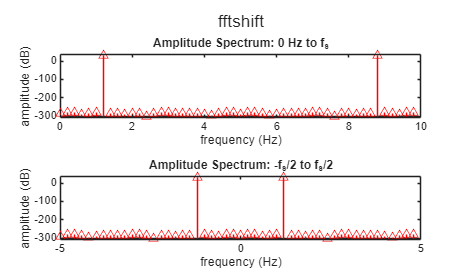

fs = 10; % sampling frequency (Hz)
fSine = 1.2; % frequency of the sine signal (Hz)
N = 50; % length of the signal in number of samples
ASine = 1; % time-domain amplitude of the sine signal
ASineFreq = ASine*N/2;
f0 = fs/N;

t = 0:1/fs:(N-1)/fs;
uSine = ASine*sin(2*pi*fSine*t); 

f = 0:f0:fs-f0;
fShift = -fs/2:f0:fs/2-f0;
USine = fft(uSine);

% plot spectrum as obtained using fft function
figure; tcl = tiledlayout(2,1); title(tcl,'fftshift')
nexttile; stem(f,db(USine),'r^','BaseValue',-300); title('Amplitude Spectrum: 0 Hz to f_s')
xlim([0,fs]); ylim([min(db(USine))-10, max(db(USine)+10)]); xlabel('frequency (Hz)');  ylabel('amplitude (dB)')
% plot shifted spectrum
nexttile; stem(fShift,db(fftshift(USine)),'r^','BaseValue',-300); title('Amplitude Spectrum: -f_s/2 to f_s/2')
xlim([-fs/2,fs/2]); ylim([min(db(USine))-10, max(db(USine)+10)]); xlabel('frequency (Hz)');  ylabel('amplitude (dB)')

## The DFT in Simulink

    To be completed.

## Further Reading and References

- R. Pintelon and J. Schoukens, *System Identification: A Frequency Domain Approach*, 2nd Edition, Wiley-IEEE Press, 2012.

- J. Schoukens, R. Pintelon and Y. Rolain, *Mastering System Identification in 100 Exercises*, Wiley-IEEE Press, 2012.